# Irminger 2 CTD Casts

First produces a rough map of the CTD casts from Irminger 2 in the vicinity of OOI assets. Each CTD cast is then plotted for temperature, salinity, and dissolved oxygen. 

Kristen Fogaren 12/3/2020

- Data was downloaded from Alfresco

- Data conversion with Seabird Software

- Processed casts in Python and output to CSV

- Read into Matab as tables

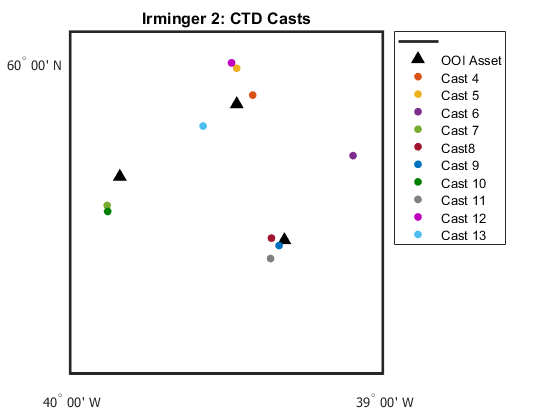

% Set up workspace 
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

cd('G:\My Drive\Matlab_work\BC\IrmingerData\Year2')
load Irm2_CTD_Casts.mat

% OOI asset locations 
ooi_latlon = [59.9341, -39.4673
    59.8177, -39.8412
    59.7155, -39.3148];
    
% Setup the Map Axes
figure
axesm('MapProjection','mercator'); 
minlat=min(ooi_latlon(:,1)); maxlat=max(ooi_latlon(:,1)); 
minlon=min(ooi_latlon(:,2)); maxlon=max(ooi_latlon(:,1)); 

% New Lat/Lon Limits
ll = [-40 59.5; -39 60.05];

setm(gca, 'MapLatLimit',[ll(1,2) ll(2,2)],...
          'MapLonLimit',[ll(1,1) ll(2,1)]);
setm(gca,'MLineLocation',1,'MLabelLocation',1,...
    'MeridianLabel','on','MLabelParallel','south'); 
setm(gca,'PLineLocation',1,'PLabelLocation',1,...
    'ParallelLabel','on','PLabelMeridian','west');
tightmap;
setm(gca,'FontWeight','normal','FontSize',10,'FontName','Tahoma','LabelUnits','dm'); 

% Add lat/lon tickmarks for every degree if the map spans 
% greater than 1.5 degrees longitude, or every quarter degree if less.
if abs(maxlon-minlon)>1.5
  setm(gca,'MLineLocation',1,'MLabelLocation',1,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',1,'PLabelLocation',1,'ParallelLabel','on','PLabelMeridian','west');
else
  setm(gca,'MLineLocation',0.25,'MLabelLocation',0.25,'MeridianLabel','on','MLabelParallel','south'); 
  setm(gca,'PLineLocation',0.25,'PLabelLocation',0.25,'ParallelLabel','on','PLabelMeridian','west');
end

% Plot Casts/OOI Assets
plotm(ooi_latlon(:,1),ooi_latlon(:,2),'^','markersize',8,'MarkerFaceColor','k',...
    'MarkerEdgeColor','k')
hold on
plotm(nanmean(at30004down.latitude),nanmean(at30004down.longitude),'.','markersize',20,'Color',red)
plotm(nanmean(at30005down.latitude),nanmean(at30005down.longitude),'.','markersize',20,'Color',yellow)
plotm(nanmean(at30006down.latitude),nanmean(at30006down.longitude),'.','markersize',20,'Color',purple)
plotm(nanmean(at30007down.latitude),nanmean(at30007down.longitude),'.','markersize',20,'Color',green)
plotm(nanmean(at30008down.latitude),nanmean(at30008down.longitude),'.','markersize',20,'Color',maroon)
plotm(nanmean(at30009down.latitude),nanmean(at30009down.longitude),'.','markersize',20,'Color',blue)
plotm(nanmean(at30010down.latitude),nanmean(at30010down.longitude),'.','markersize',20,'Color',forestgreen)
plotm(nanmean(at30011down.latitude),nanmean(at30011down.longitude),'.','markersize',20,'Color',grey)
plotm(nanmean(at30012down.latitude),nanmean(at30012down.longitude),'.','markersize',20,'Color',brightpurple)
plotm(nanmean(at30013down.latitude),nanmean(at30013down.longitude),'.','markersize',20,'Color',cyan)

title('Irminger 2: CTD Casts')
legend('','OOI Asset','Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Cast 11','Cast 12','Cast 13','Location','bestoutside')

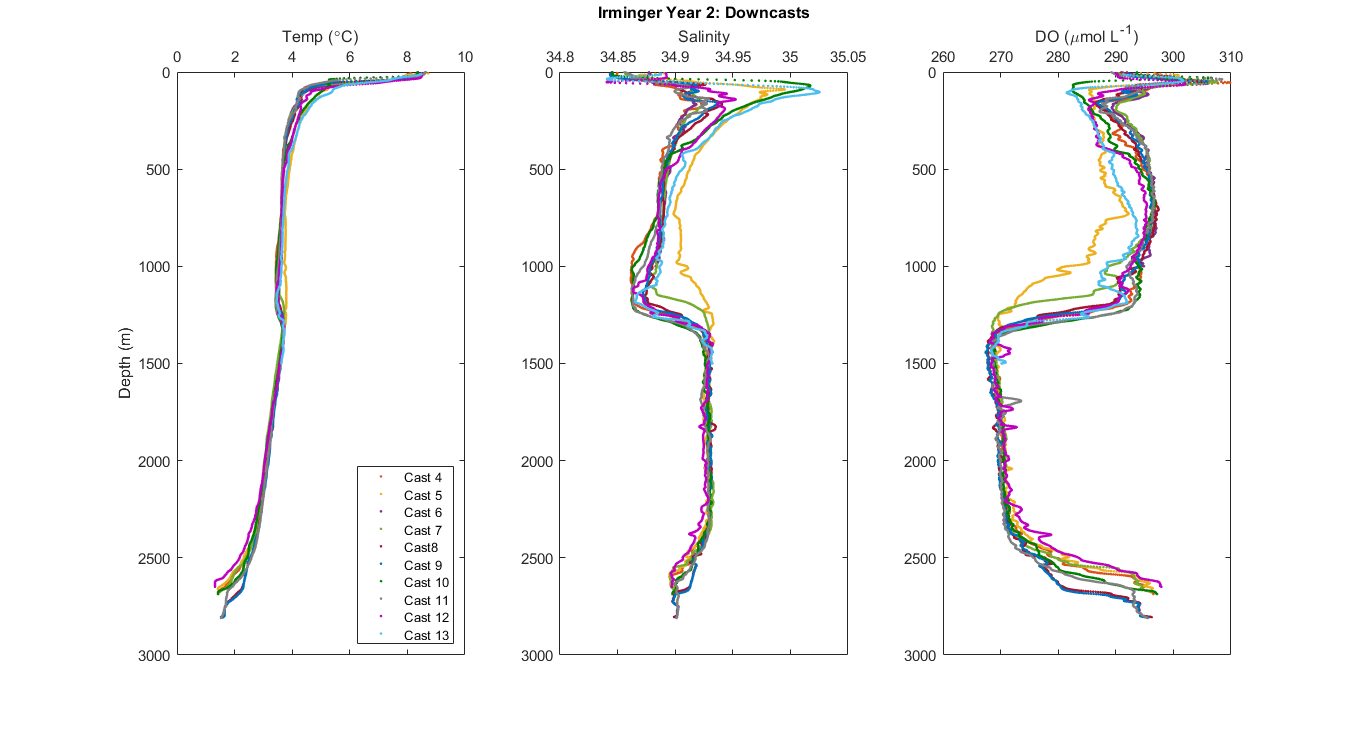

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30004down.t090C,at30004down.depSM,'.','Color',red)
hold on
plot(at30005down.t090C,at30005down.depSM,'.','Color',yellow)
plot(at30006down.t090C,at30006down.depSM,'.','Color',purple)
plot(at30007down.t090C,at30007down.depSM,'.','Color',green)
plot(at30008down.t090C,at30008down.depSM,'.','Color',maroon)
plot(at30009down.t090C,at30009down.depSM,'.','Color',blue)
plot(at30010down.t090C,at30010down.depSM,'.','Color',forestgreen)
plot(at30011down.t090C,at30011down.depSM,'.','Color',grey)
plot(at30012down.t090C,at30012down.depSM,'.','Color',brightpurple)
plot(at30013down.t090C,at30013down.depSM,'.','Color',cyan)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Cast 11','Cast 12','Cast 13','Location','SE')

s2 = subplot(1,3,2);
plot(at30004down.sal00,at30004down.depSM,'.','Color',red)
hold on
plot(at30005down.sal00,at30005down.depSM,'.','Color',yellow)
plot(at30006down.sal00,at30006down.depSM,'.','Color',purple)
plot(at30007down.sal00,at30007down.depSM,'.','Color',green)
plot(at30008down.sal00,at30008down.depSM,'.','Color',maroon)
plot(at30009down.sal00,at30009down.depSM,'.','Color',blue)
plot(at30010down.sal00,at30010down.depSM,'.','Color',forestgreen)
plot(at30011down.sal00,at30011down.depSM,'.','Color',grey)
plot(at30012down.sal00,at30012down.depSM,'.','Color',brightpurple)
plot(at30013down.sal00,at30013down.depSM,'.','Color',cyan)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Downcasts')

s3 = subplot(1,3,3);
plot(at30004down.sbeox0MLL*44.661,at30004down.depSM,'.','Color',red)
hold on
plot(at30005down.sbeox0MLL*44.661,at30005down.depSM,'.','Color',yellow)
plot(at30006down.sbeox0MLL*44.661,at30006down.depSM,'.','Color',purple)
plot(at30007down.sbeox0MLL*44.661,at30007down.depSM,'.','Color',green)
plot(at30008down.sbeox0MLL*44.661,at30008down.depSM,'.','Color',maroon)
plot(at30009down.sbeox0MLL*44.661,at30009down.depSM,'.','Color',blue)
plot(at30010down.sbeox0MLL*44.661,at30010down.depSM,'.','Color',forestgreen)
plot(at30011down.sbeox0MLL*44.661,at30011down.depSM,'.','Color',grey)
plot(at30012down.sbeox0MLL*44.661,at30012down.depSM,'.','Color',brightpurple)
plot(at30013down.sbeox0MLL*44.661,at30013down.depSM,'.','Color',cyan)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

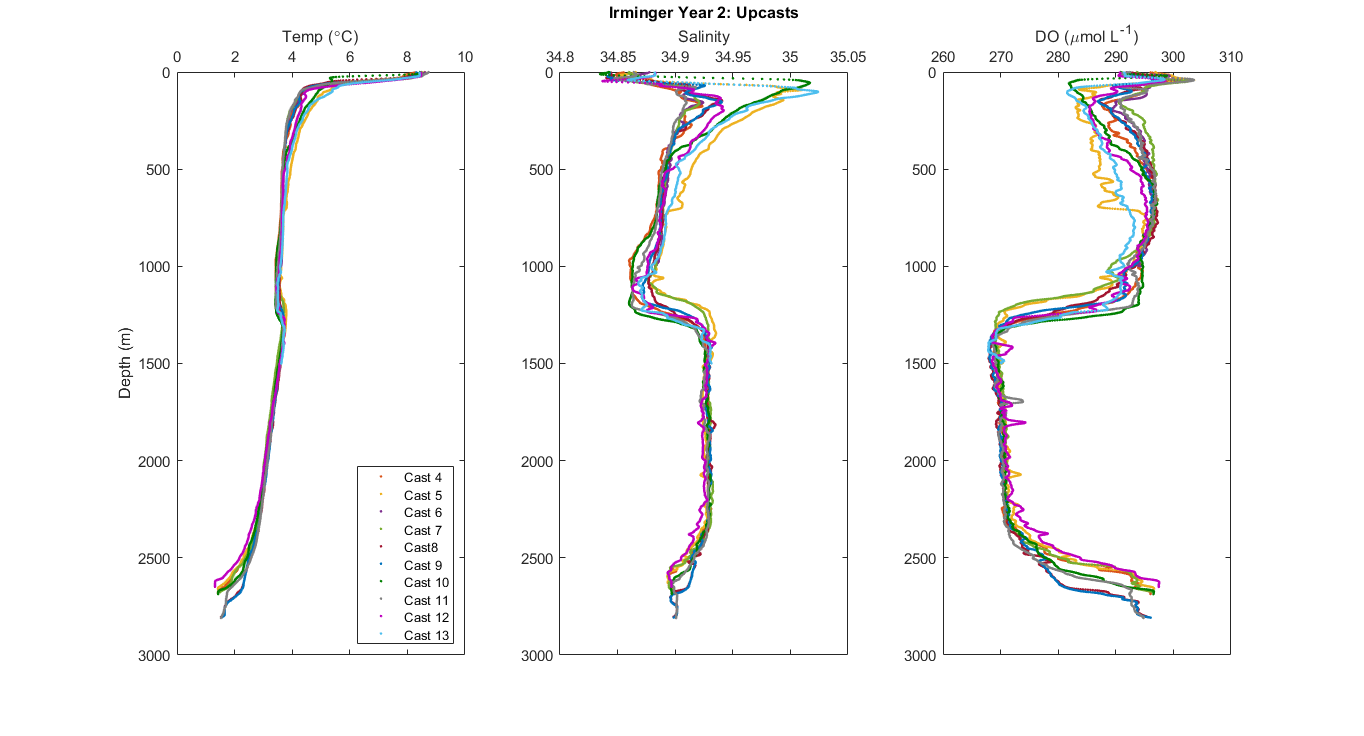

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30004up.t090C,at30004up.depSM,'.','Color',red)
hold on
plot(at30005up.t090C,at30005up.depSM,'.','Color',yellow)
plot(at30006up.t090C,at30006up.depSM,'.','Color',purple)
plot(at30007up.t090C,at30007up.depSM,'.','Color',green)
plot(at30008up.t090C,at30008up.depSM,'.','Color',maroon)
plot(at30009up.t090C,at30009up.depSM,'.','Color',blue)
plot(at30010up.t090C,at30010up.depSM,'.','Color',forestgreen)
plot(at30011up.t090C,at30011up.depSM,'.','Color',grey)
plot(at30012up.t090C,at30012up.depSM,'.','Color',brightpurple)
plot(at30013up.t090C,at30013up.depSM,'.','Color',cyan)
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Cast 4','Cast 5','Cast 6','Cast 7','Cast8','Cast 9',...
    'Cast 10','Cast 11','Cast 12','Cast 13','Location','SE')

s2 = subplot(1,3,2);
plot(at30004up.sal00,at30004up.depSM,'.','Color',red)
hold on
plot(at30005up.sal00,at30005up.depSM,'.','Color',yellow)
plot(at30006up.sal00,at30006up.depSM,'.','Color',purple)
plot(at30007up.sal00,at30007up.depSM,'.','Color',green)
plot(at30008up.sal00,at30008up.depSM,'.','Color',maroon)
plot(at30009up.sal00,at30009up.depSM,'.','Color',blue)
plot(at30010up.sal00,at30010up.depSM,'.','Color',forestgreen)
plot(at30011up.sal00,at30011up.depSM,'.','Color',grey)
plot(at30012up.sal00,at30012up.depSM,'.','Color',brightpurple)
plot(at30013up.sal00,at30013up.depSM,'.','Color',cyan)
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Upcasts')

s3 = subplot(1,3,3);
plot(at30004up.sbeox0MLL*44.661,at30004up.depSM,'.','Color',red)
hold on
plot(at30005up.sbeox0MLL*44.661,at30005up.depSM,'.','Color',yellow)
plot(at30006up.sbeox0MLL*44.661,at30006up.depSM,'.','Color',purple)
plot(at30007up.sbeox0MLL*44.661,at30007up.depSM,'.','Color',green)
plot(at30008up.sbeox0MLL*44.661,at30008up.depSM,'.','Color',maroon)
plot(at30009up.sbeox0MLL*44.661,at30009up.depSM,'.','Color',blue)
plot(at30010up.sbeox0MLL*44.661,at30010up.depSM,'.','Color',forestgreen)
plot(at30011up.sbeox0MLL*44.661,at30011up.depSM,'.','Color',grey)
plot(at30012up.sbeox0MLL*44.661,at30012up.depSM,'.','Color',brightpurple)
plot(at30013up.sbeox0MLL*44.661,at30013up.depSM,'.','Color',cyan)
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

- Colors in CTD plots correspond to location colors in the map above. 

## Upcasts versus Downcasts 

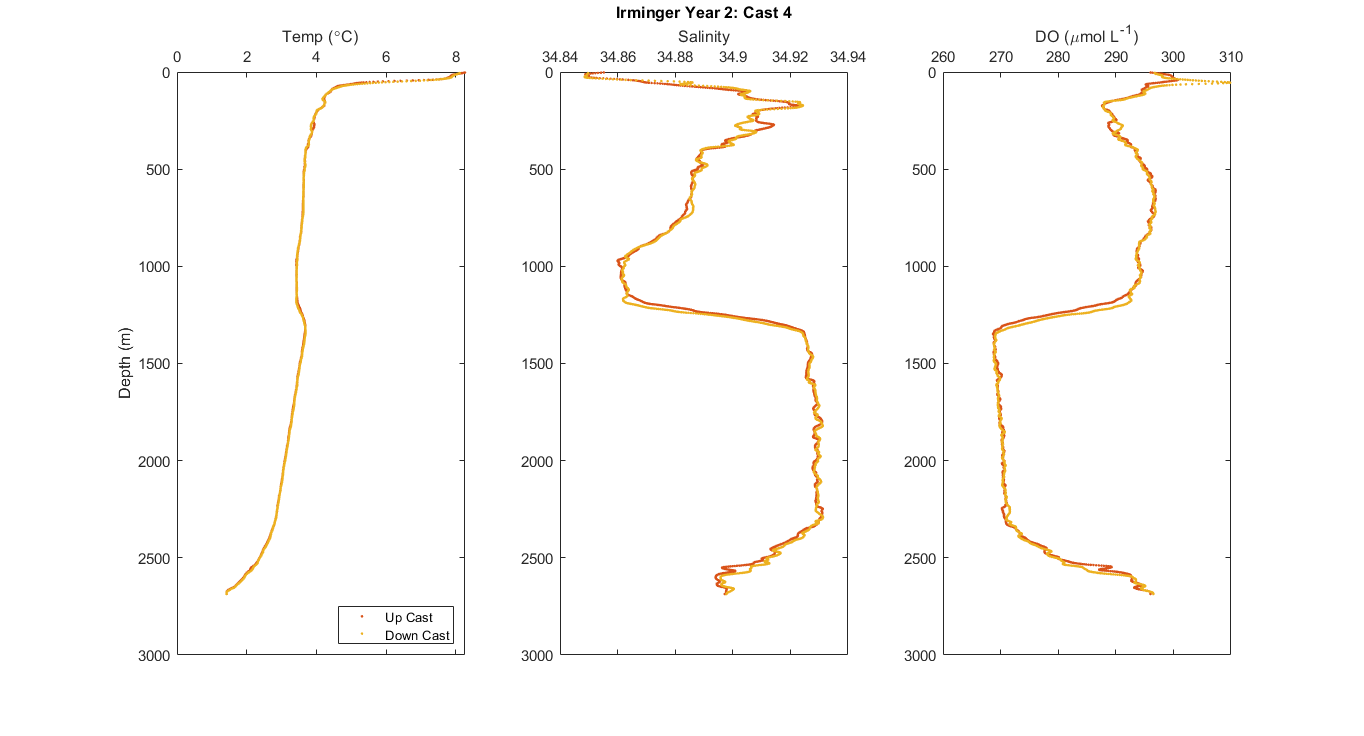

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30004up.t090C,at30004up.depSM,'.','Color',red);
hold on
plot(at30004down.t090C,at30004down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30004up.sal00,at30004up.depSM,'.','Color',red);
hold on
plot(at30004down.sal00,at30004down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 4')

s3 = subplot(1,3,3);
plot(at30004up.sbeox0MLL*44.661,at30004up.depSM,'.','Color',red);
hold on
plot(at30004down.sbeox0MLL*44.661,at30004down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

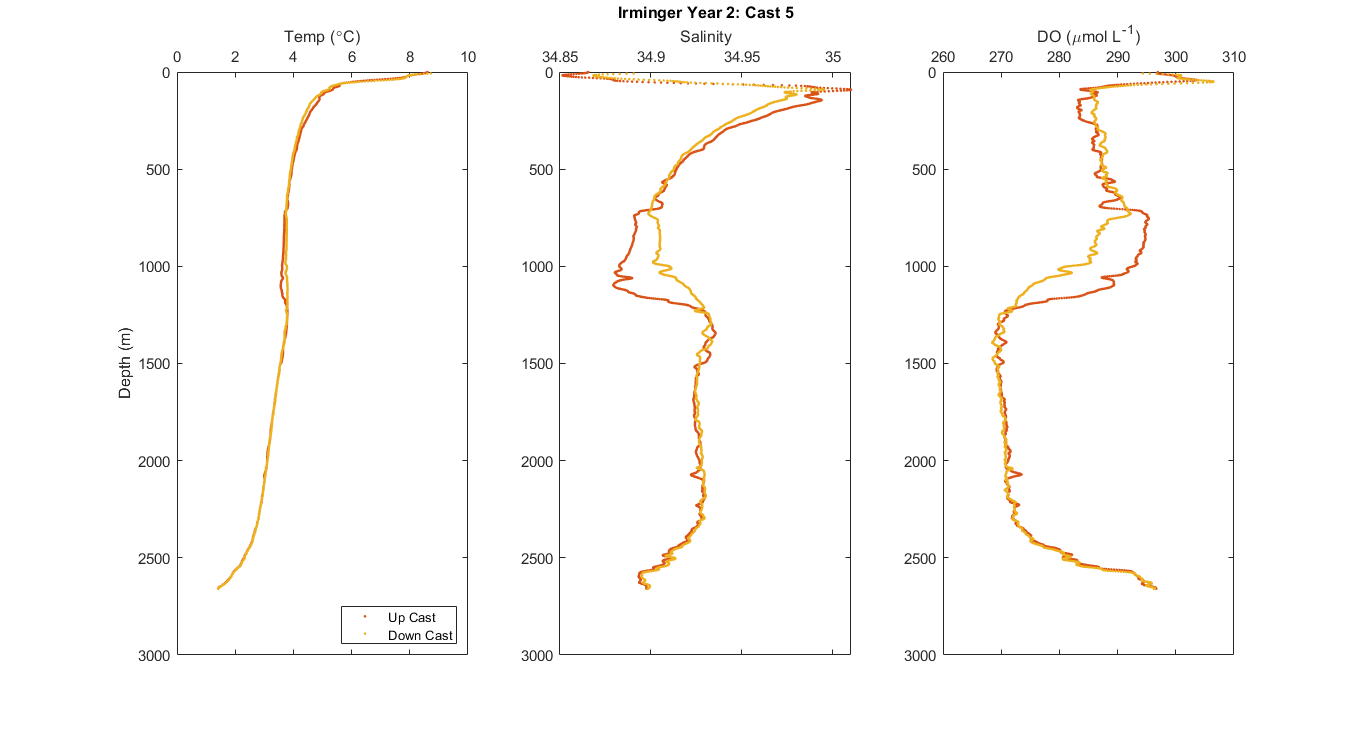

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30005up.t090C,at30005up.depSM,'.','Color',red);
hold on
plot(at30005down.t090C,at30005down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30005up.sal00,at30005up.depSM,'.','Color',red);
hold on
plot(at30005down.sal00,at30005down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 5')

s3 = subplot(1,3,3);
plot(at30005up.sbeox0MLL*44.661,at30005up.depSM,'.','Color',red);
hold on
plot(at30005down.sbeox0MLL*44.661,at30005down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

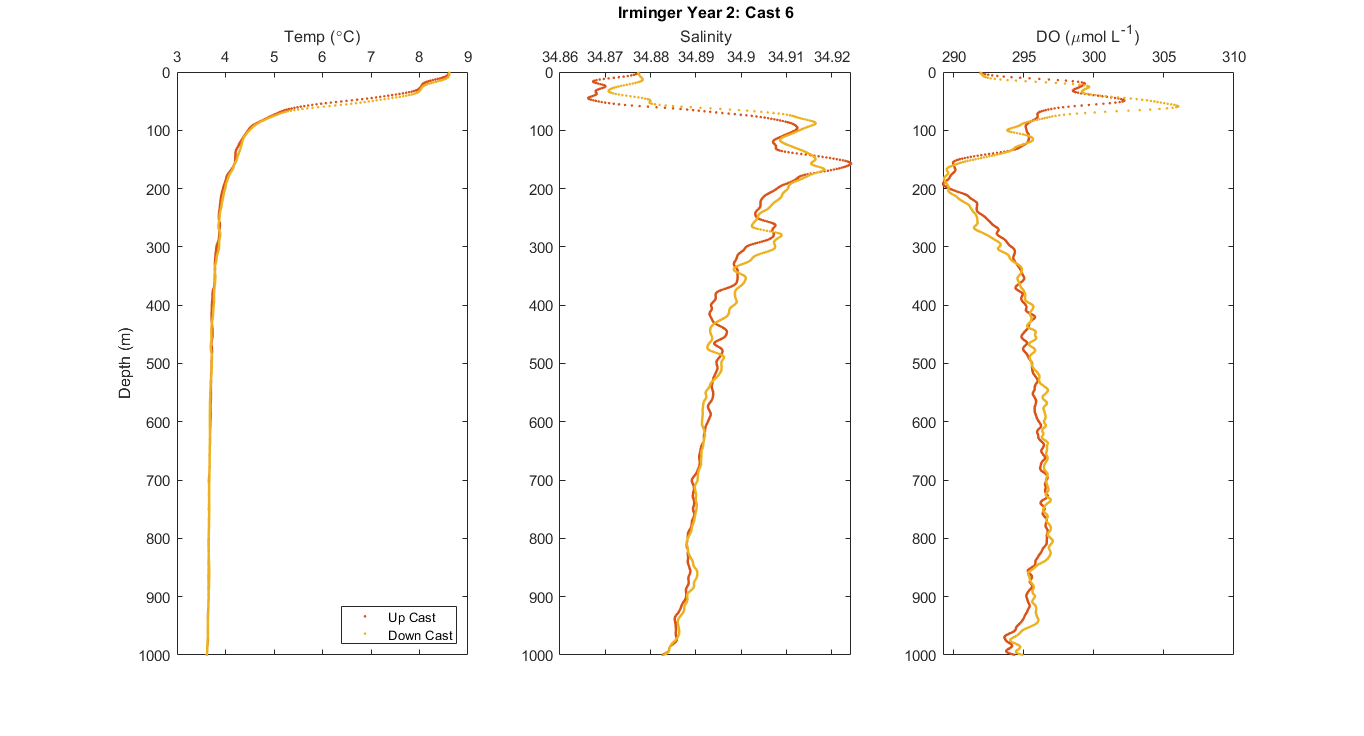

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30006up.t090C,at30006up.depSM,'.','Color',red);
hold on
plot(at30006down.t090C,at30006down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30006up.sal00,at30006up.depSM,'.','Color',red);
hold on
plot(at30006down.sal00,at30006down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 6')

s3 = subplot(1,3,3);
plot(at30006up.sbeox0MLL*44.661,at30006up.depSM,'.','Color',red);
hold on
plot(at30006down.sbeox0MLL*44.661,at30006down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

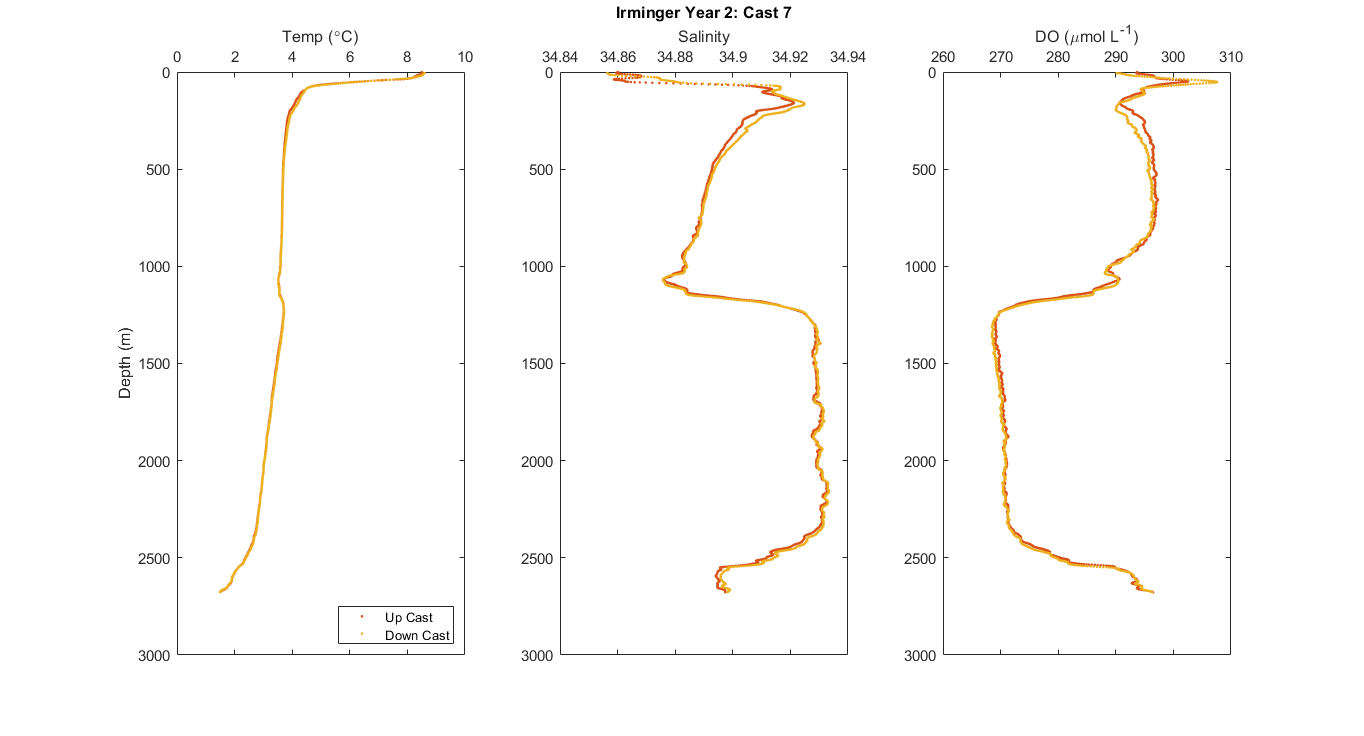

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30007up.t090C,at30007up.depSM,'.','Color',red);
hold on
plot(at30007down.t090C,at30007down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30007up.sal00,at30007up.depSM,'.','Color',red);
hold on
plot(at30007down.sal00,at30007down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 7')

s3 = subplot(1,3,3);
plot(at30007up.sbeox0MLL*44.661,at30007up.depSM,'.','Color',red);
hold on
plot(at30007down.sbeox0MLL*44.661,at30007down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

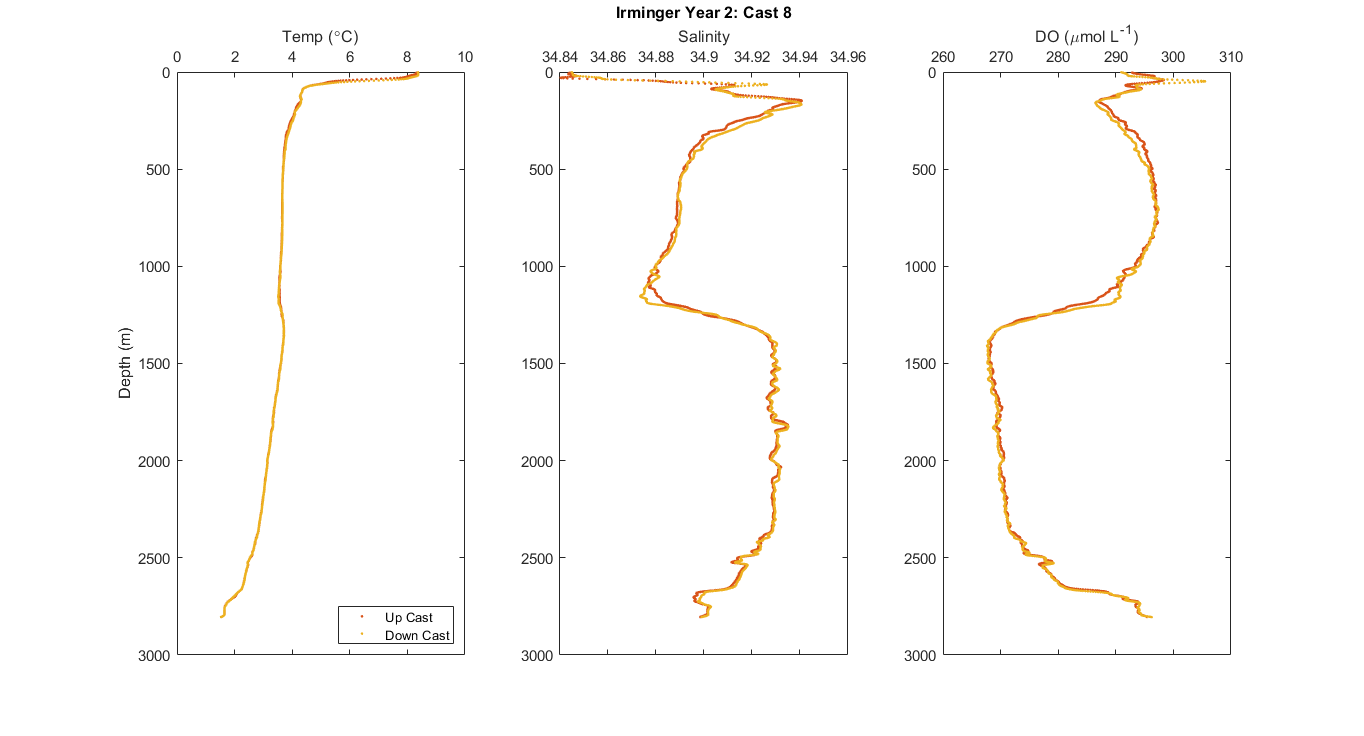

f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30008up.t090C,at30008up.depSM,'.','Color',red);
hold on
plot(at30008down.t090C,at30008down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30008up.sal00,at30008up.depSM,'.','Color',red);
hold on
plot(at30008down.sal00,at30008down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 8')

s3 = subplot(1,3,3);
plot(at30008up.sbeox0MLL*44.661,at30008up.depSM,'.','Color',red);
hold on
plot(at30008down.sbeox0MLL*44.661,at30008down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

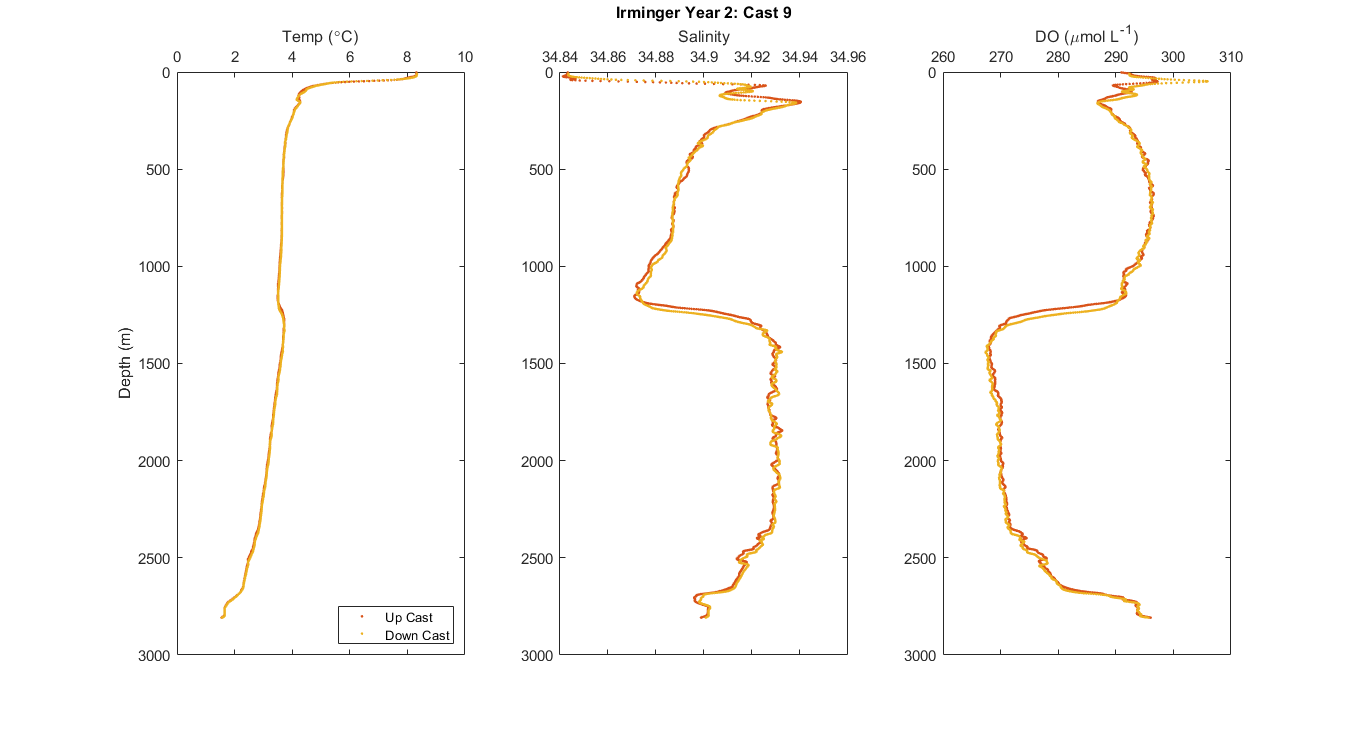


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30009up.t090C,at30009up.depSM,'.','Color',red);
hold on
plot(at30009down.t090C,at30009down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30009up.sal00,at30009up.depSM,'.','Color',red);
hold on
plot(at30009down.sal00,at30009down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 9')

s3 = subplot(1,3,3);
plot(at30009up.sbeox0MLL*44.661,at30009up.depSM,'.','Color',red);
hold on
plot(at30009down.sbeox0MLL*44.661,at30009down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

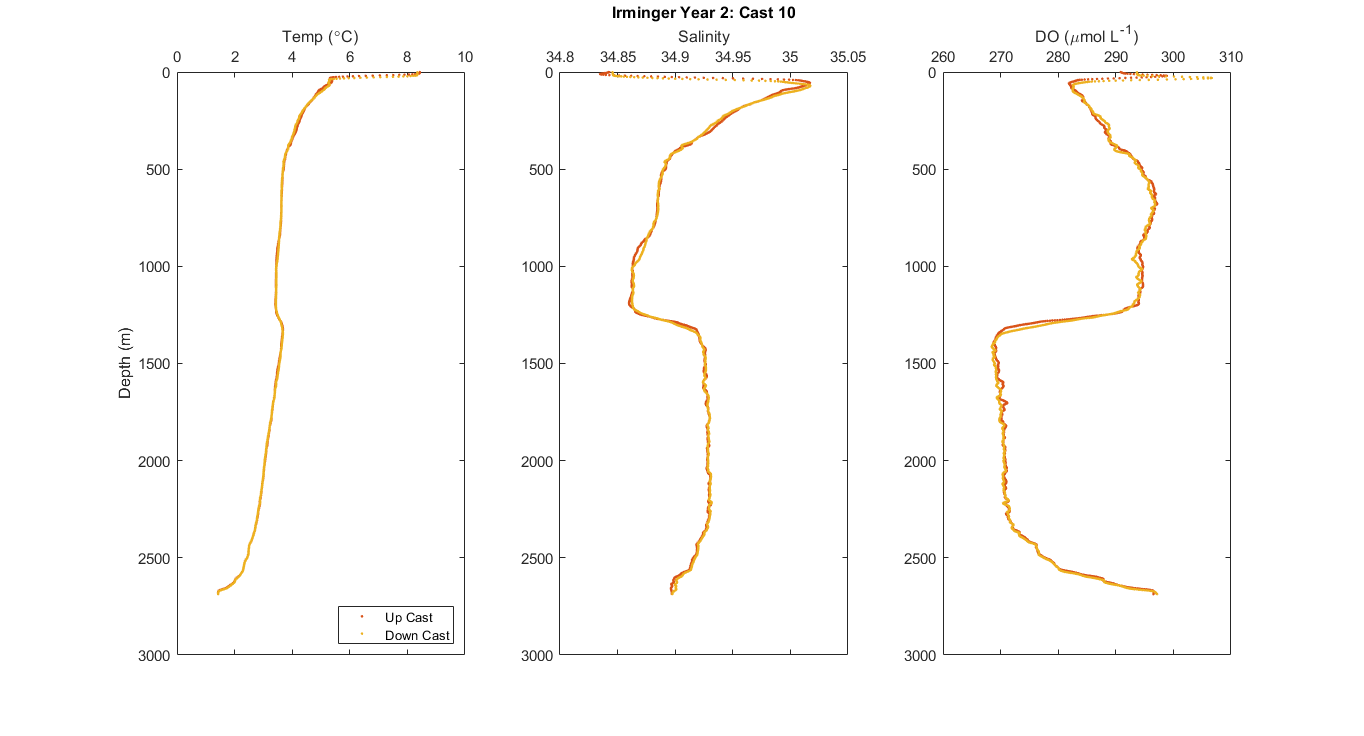


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30010up.t090C,at30010up.depSM,'.','Color',red);
hold on
plot(at30010down.t090C,at30010down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30010up.sal00,at30010up.depSM,'.','Color',red);
hold on
plot(at30010down.sal00,at30010down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 10')

s3 = subplot(1,3,3);
plot(at30010up.sbeox0MLL*44.661,at30010up.depSM,'.','Color',red);
hold on
plot(at30010down.sbeox0MLL*44.661,at30010down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

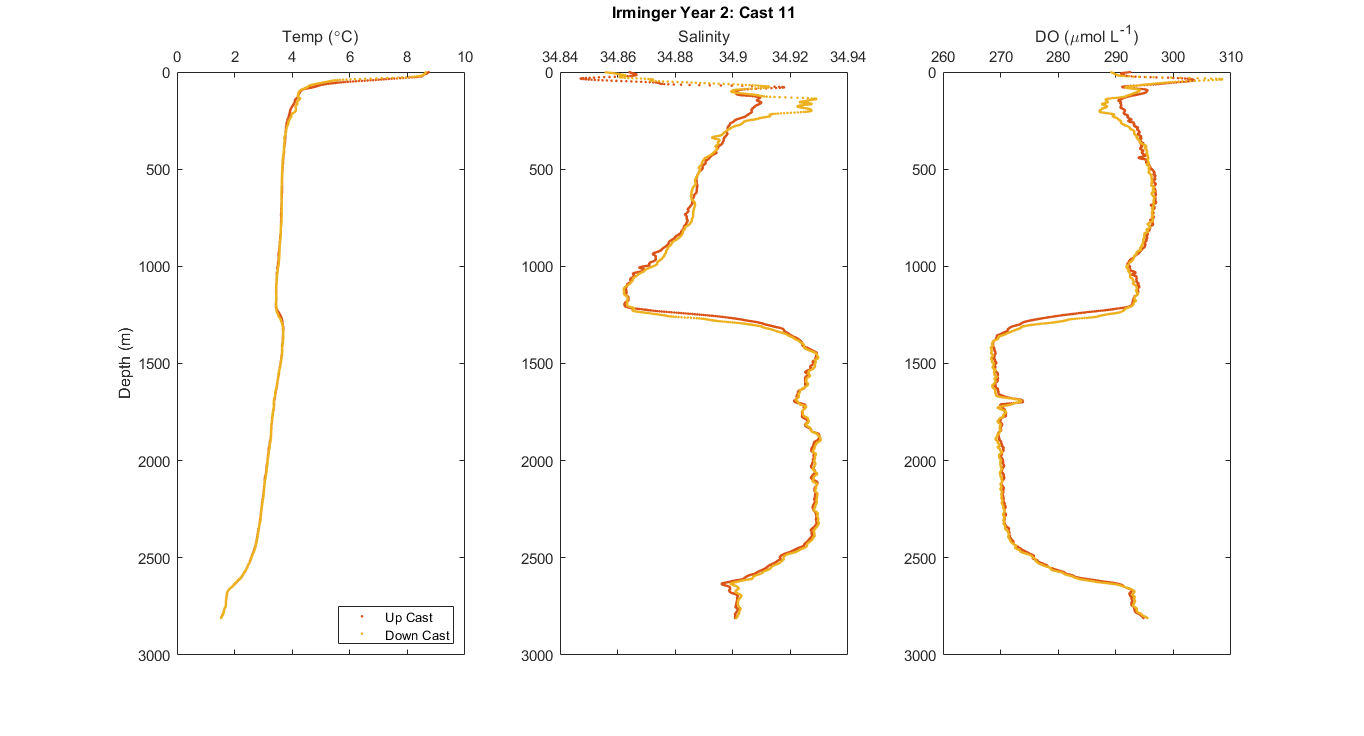


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30011up.t090C,at30011up.depSM,'.','Color',red);
hold on
plot(at30011down.t090C,at30011down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30011up.sal00,at30011up.depSM,'.','Color',red);
hold on
plot(at30011down.sal00,at30011down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 11')

s3 = subplot(1,3,3);
plot(at30011up.sbeox0MLL*44.661,at30011up.depSM,'.','Color',red);
hold on
plot(at30011down.sbeox0MLL*44.661,at30011down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

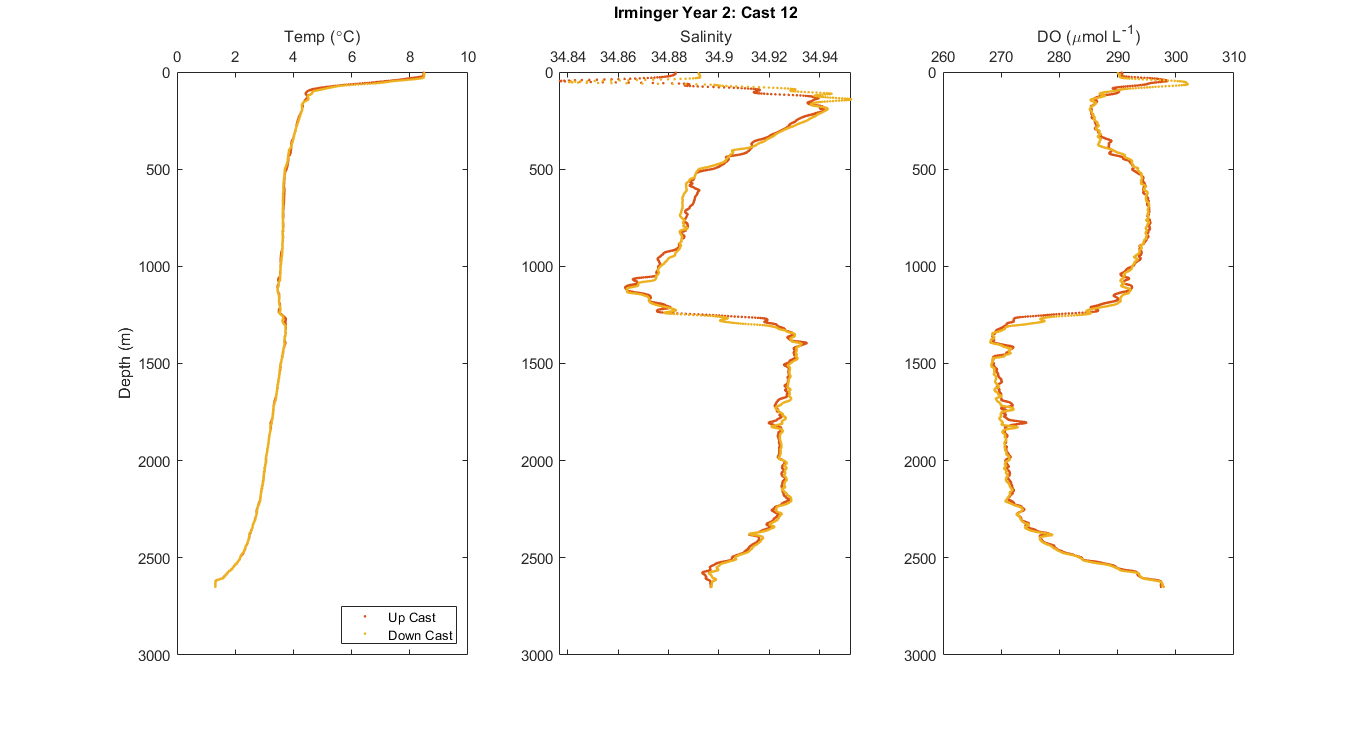


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30012up.t090C,at30012up.depSM,'.','Color',red);
hold on
plot(at30012down.t090C,at30012down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30012up.sal00,at30012up.depSM,'.','Color',red);
hold on
plot(at30012down.sal00,at30012down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 12')

s3 = subplot(1,3,3);
plot(at30012up.sbeox0MLL*44.661,at30012up.depSM,'.','Color',red);
hold on
plot(at30012down.sbeox0MLL*44.661,at30012down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')

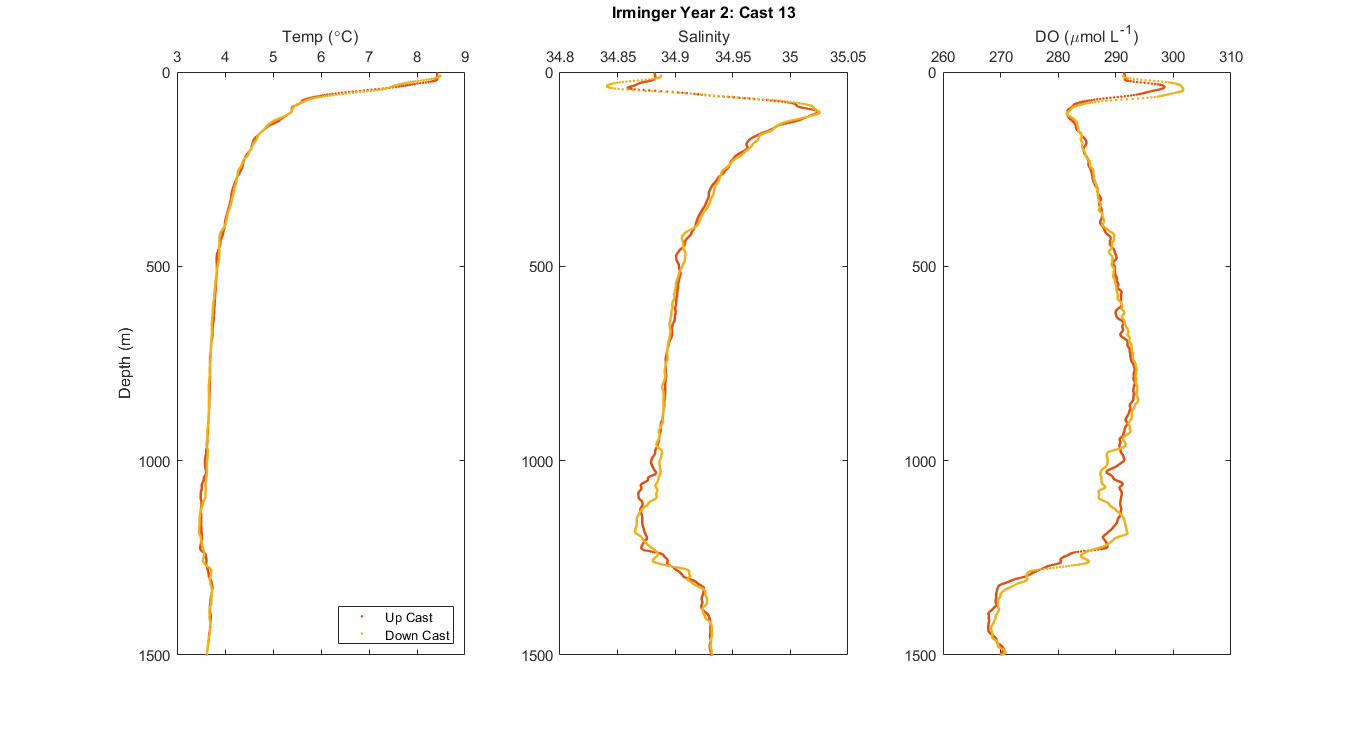


f1 = figure;
set(f1, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);

s1 = subplot(1,3,1);
plot(at30013up.t090C,at30013up.depSM,'.','Color',red);
hold on
plot(at30013down.t090C,at30013down.depSM,'.','Color',yellow);
axis ij
s1.XAxisLocation = 'top';
xlabel('Temp (\circC)')
ylabel('Depth (m)')
legend('Up Cast','Down Cast','Location','SE')

s2 = subplot(1,3,2);
plot(at30013up.sal00,at30013up.depSM,'.','Color',red);
hold on
plot(at30013down.sal00,at30013down.depSM,'.','Color',yellow);
axis ij
s2.XAxisLocation = 'top';
xlabel('Salinity')
title('Irminger Year 2: Cast 13')

s3 = subplot(1,3,3);
plot(at30013up.sbeox0MLL*44.661,at30013up.depSM,'.','Color',red);
hold on
plot(at30013down.sbeox0MLL*44.661,at30013down.depSM,'.','Color',yellow);
axis ij
s3.XAxisLocation = 'top';
xlabel('DO (\mumol L^-^1)')